clear; close all;

Lab 6

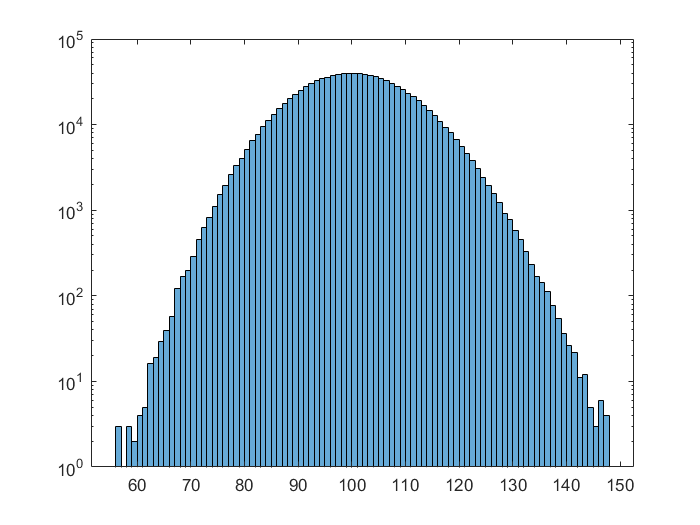

fakedata = poissrnd(100,1,1000000);
histogram(fakedata,'BinWidth',1)
set(gca,'YScale','log')


%problem 1 finding the 5sigma of the data

prob_5_U = normcdf(5,"upper");
prob_5_L = normcdf(5);
fakeinv = poissinv(prob_5_U,100);
fakeinv2 = poissinv(prob_5_L,100);
fakeinv

fakeinv = 54

fakeinv2

fakeinv2 = 154

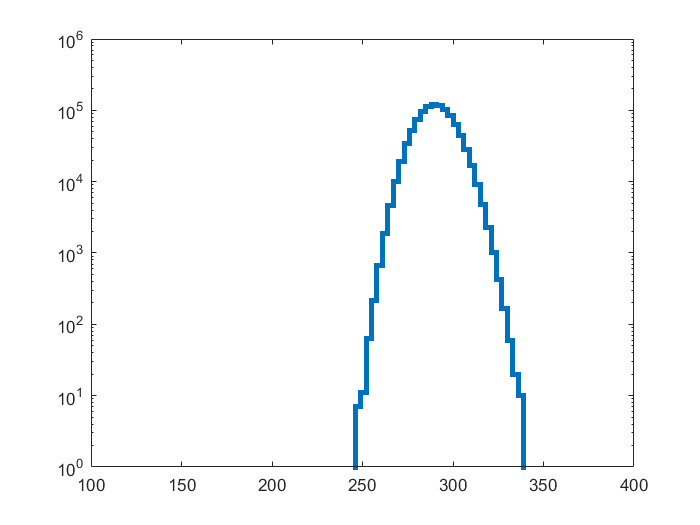


%problem 2 

prob8 = normcdf(8);
fake_signal = poissinv(prob8,100);
% fake_signal

newdata = fakedata + fake_signal;
histogram(newdata,'BinWidth',3,'DisplayStyle','stairs','LineWidth',3)
xlim([100 400])
set(gca,'YScale','log')

The observed signal is slighty biased because it is a Poisson distribution, however because we have a large mean the Poisson distribution becomes more and more like a normal distribution so there is a slight skewing to the left and therefore more likely to be less than the observed signal.

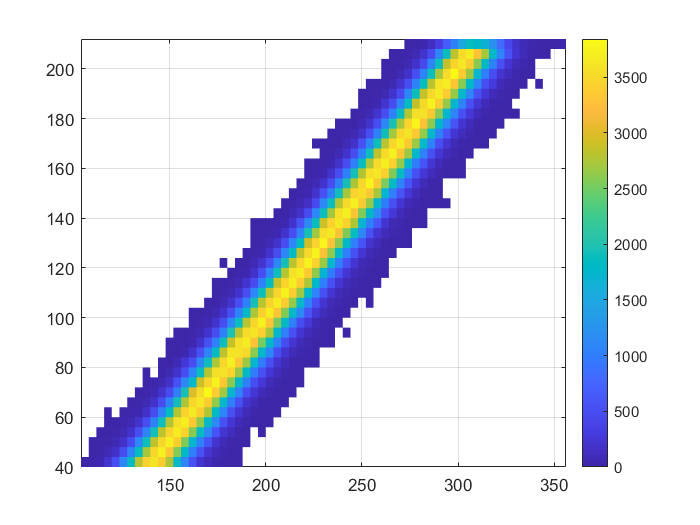

%problem 3
injsignal = unifrnd(40,fake_signal+20,1,1000000);
data = fakedata + injsignal;

H = histogram2(data,injsignal,'BinWidth',4,'DisplayStyle','tile');
colorbar

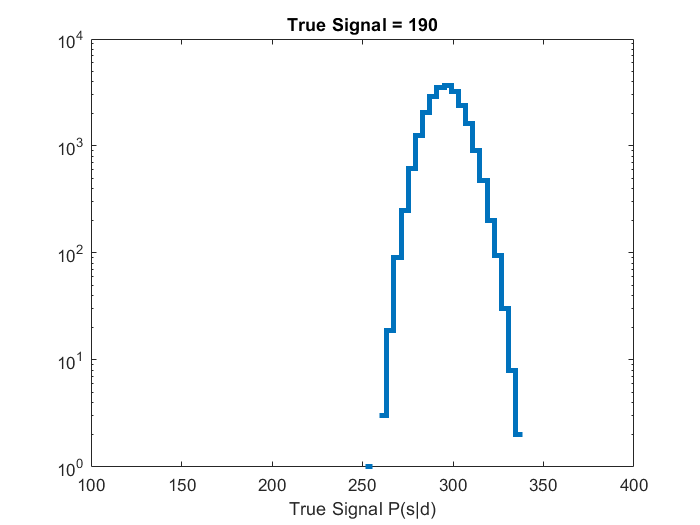


[T,A,B] = histcounts2(data,injsignal,[63 43]);

hor = T(:,40);

stairs(A(1:end-1),hor,'LineWidth',3)
title('True Signal = 190')
xlabel('True Signal P(s|d)')
xlim([100 400])
set(gca,'Yscale','log')

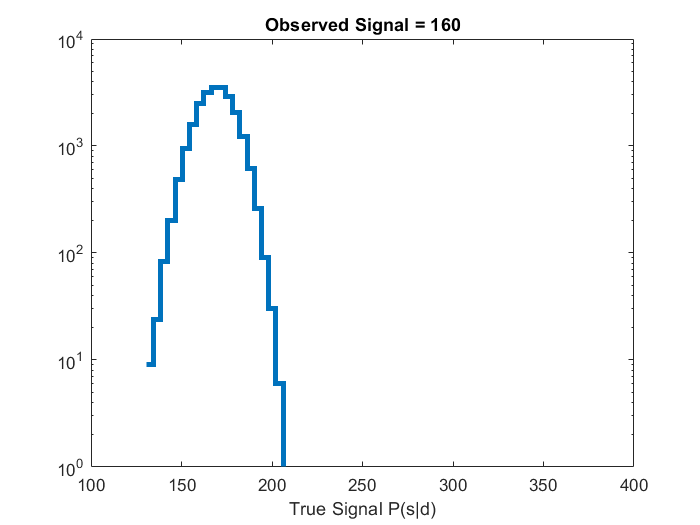


vert = T(42,:);
stairs(B(1:end-1),vert,'LineWidth',3)
title('Observed Signal = 160')
xlabel('True Signal P(s|d)')
xlim([100 400])
set(gca,'Yscale','log')